%% =========================================================
%  SCRIPT 1A: LINEARIZE → LQR → CLOSED-LOOP DATA → TWIN NN
%% =========================================================
clc; clear; close all;

%% PARAMETERS
A1=615.75; A2=615.75; A3=615.75;
a12=5.0671; a23=5.0671; a3=5.0671;
beta12=0.9; beta23=0.8; beta3=0.3;
k1=75; k2=75; dt=0.5;

%% OPERATING POINT
h0 = [48.9169; 44.4106; 39.3580];

F12_0 = beta12*a12*sqrt(h0(1)-h0(2));
F23_0 = beta23*a23*sqrt(h0(2)-h0(3));
F3_0  = beta3*a3*sqrt(h0(3));
u0    = [F12_0/k1; max((F3_0-F23_0)/k2, 0)];
disp(['Equilibrium inputs: u1_0=',num2str(u0(1),'%.4f'),' u2_0=',num2str(u0(2),'%.4f')]);

Equilibrium inputs: u1_0=0.1291 u2_0=0.0057



%% -------- LINEARIZATION (Jacobians at h0) --------
c12 = beta12*a12 / (2*sqrt(h0(1)-h0(2)));
c23 = beta23*a23 / (2*sqrt(h0(2)-h0(3)));
c3  = beta3*a3   / (2*sqrt(h0(3)));

A_lin = [-c12/A1,         c12/A1,              0     ;
          c12/A2,   -(c12+c23)/A2,         c23/A2    ;
          0,              c23/A3,     -(c23+c3)/A3   ];

B_lin = [k1/A1,  0    ;
         0,      0    ;
         0,   k2/A3   ];

% Check controllability
Co = ctrb(A_lin, B_lin);
disp(['Controllability rank: ', num2str(rank(Co)), ' (need 3)']);

Controllability rank: 3 (need 3)



%% -------- LQR CONTROLLER DESIGN --------
Q = diag([10, 10, 10]);   % penalise level errors equally
R = diag([0.1, 0.1]);     % moderate input cost
K_lqr = lqr(A_lin, B_lin, Q, R);
disp('LQR gain K:'); disp(K_lqr);

LQR gain K:
    9.9892    2.4497    0.0029
    0.0029    2.0565    9.9888




% Verify closed-loop poles are stable
cl_poles = eig(A_lin - B_lin*K_lqr);
disp('Closed-loop poles:'); disp(cl_poles);

Closed-loop poles:
   -0.0039
   -1.2180
   -1.2180




%% -------- HELPER: equilibrium input for any setpoint --------
function u_eq = getUeq(h_ref, beta12,a12,beta23,a23,beta3,a3,k1,k2)
    F12e = beta12*a12*sqrt(max(h_ref(1)-h_ref(2),0));
    F23e = beta23*a23*sqrt(max(h_ref(2)-h_ref(3),0));
    F3e  = beta3*a3  *sqrt(max(h_ref(3),0));
    u_eq = [F12e/k1;  max((F3e-F23e)/k2, 0)];
end

%% -------- CLOSED-LOOP SIMULATION --------
T = 3000;  time = 0:dt:T;  Nsim = length(time);
h = h0;
data_cl = zeros(Nsim, 6);  % [t, u1, u2, h1_meas, h2_meas, h3_meas]

for i = 1:Nsim
    t = time(i);

    % --- Step setpoint sequence (excites multiple regions) ---
    period = mod(t, 600);
    if     period < 150,  h_ref = h0 + [ 6;  5;  3];
    elseif period < 300,  h_ref = h0 + [-4; -3; -2];
    elseif period < 450,  h_ref = h0 + [ 2;  5;  4];
    else,                 h_ref = h0 + [-3;  2; -3];
    end
    h_ref = max(h_ref, [2;2;2]);   % keep physically meaningful

    u_eq   = getUeq(h_ref, beta12,a12,beta23,a23,beta3,a3,k1,k2);
    h_meas = h + 0.05*randn(3,1);   % sensor noise (clean, no fault)

    % LQR law: u = u_eq - K*(h_measured - h_ref)
    u = u_eq - K_lqr*(h_meas - h_ref);
    u = max(u, 0);                   % non-negative pump flows

    data_cl(i,:) = [t, u(1), u(2), h_meas(1), h_meas(2), h_meas(3)];

    % Advance nonlinear plant
    h1=h(1); h2=h(2); h3=h(3);
    F12=beta12*a12*sqrt(max(h1-h2,0));
    F23=beta23*a23*sqrt(max(h2-h3,0));
    F3 =beta3*a3  *sqrt(max(h3,0));
    dh = [(k1*u(1)-F12)/A1; (F12-F23)/A2; (F23-F3+k2*u(2))/A3];
    h  = max(h + dt*dh, 0);
end

%% -------- BUILD SEQUENCE DATASET (seq_len=5) --------
seq_len = 5;
u1_col=data_cl(:,2); u2_col=data_cl(:,3);
h1_col=data_cl(:,4); h2_col=data_cl(:,5); h3_col=data_cl(:,6);

X=[]; Y=[];
for k = seq_len+1 : Nsim
    x = [u1_col(k-1); u2_col(k-1);
         h1_col(k-1:-1:k-seq_len);
         h2_col(k-1:-1:k-seq_len);
         h3_col(k-1:-1:k-seq_len)];   % 17×1
    y = [h1_col(k); h2_col(k); h3_col(k)];
    X=[X, x];  Y=[Y, y];
end

[Xn, Xps] = mapminmax(X);
[Yn, Yps] = mapminmax(Y);

%% -------- TRAIN DIGITAL TWIN NN --------
net_twin = feedforwardnet([20 10]);
net_twin.trainFcn = 'trainlm';
net_twin.performFcn = 'mse';
net_twin.divideParam.trainRatio = 0.70;
net_twin.divideParam.valRatio   = 0.15;
net_twin.divideParam.testRatio  = 0.15;
net_twin = train(net_twin, Xn, Yn);

% Training performance check
Y_pred_n = net_twin(Xn);
Y_pred   = mapminmax('reverse', Y_pred_n, Yps);
rmse_h1  = sqrt(mean((Y(1,:)-Y_pred(1,:)).^2));
disp(['Twin RMSE h1=',num2str(rmse_h1,'%.4f'),' h2=', ...
      num2str(sqrt(mean((Y(2,:)-Y_pred(2,:)).^2)),'%.4f'),' h3=', ...
      num2str(sqrt(mean((Y(3,:)-Y_pred(3,:)).^2)),'%.4f')]);

Twin RMSE h1=0.0737 h2=0.0575 h3=0.0555



figure;
subplot(3,1,1); plot(Y(1,:),'b'); hold on; plot(Y_pred(1,:),'r--'); title('h1'); legend('True','Twin');
subplot(3,1,2); plot(Y(2,:),'b'); hold on; plot(Y_pred(2,:),'r--'); title('h2');
subplot(3,1,3); plot(Y(3,:),'b'); hold on; plot(Y_pred(3,:),'r--'); title('h3');

%% SAVE
targetFolder = 'E:\MATLAB File\Closed Loop system';
save(fullfile(targetFolder,'tank_models.mat'), ...
     'net_twin','Xps','Yps','K_lqr','h0','u0','seq_len');
disp('✅ tank_models.mat saved');

✅ tank_models.mat saved


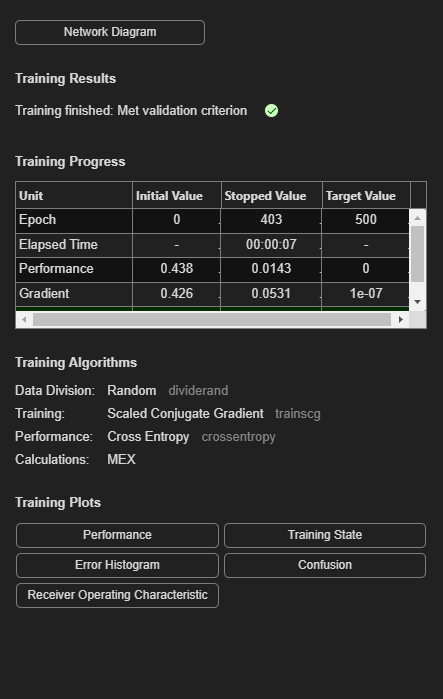


%% =========================================================
%  SCRIPT 1B (FIXED): FAULTY DATA → IMPROVED FAULT CLASSIFIER
%  Fix: Windowed residual statistics to separate Drift vs Stuck
%% =========================================================
clc; clear; close all;

%% ---- LOAD TWIN + CONTROLLER ----
ld      = load('E:\MATLAB File\Closed Loop system\tank_models.mat');
net_twin = ld.net_twin; Xps = ld.Xps; Yps = ld.Yps;
K_lqr   = ld.K_lqr;    h0  = ld.h0;  u0  = ld.u0;
seq_len = ld.seq_len;

%% ---- PARAMETERS ----
A1=615.75; A2=615.75; A3=615.75;
a12=5.0671; a23=5.0671; a3=5.0671;
beta12=0.9; beta23=0.8; beta3=0.3;
k1=75; k2=75; dt=0.5;

function u_eq = getUeq_B(h_ref,beta12,a12,beta23,a23,beta3,a3,k1,k2)
    F12e = beta12*a12*sqrt(max(h_ref(1)-h_ref(2),0));
    F23e = beta23*a23*sqrt(max(h_ref(2)-h_ref(3),0));
    F3e  = beta3*a3  *sqrt(max(h_ref(3),0));
    u_eq = [F12e/k1; max((F3e-F23e)/k2,0)];
end

%% ---- SIMULATION SETTINGS ----
T    = 2400;
time = 0:dt:T;
Nsim = length(time);

h_plant = h0;
h_pred  = h0;
h_hist  = repmat(h0, 1, seq_len);

h_ref = h0;
u_eq  = getUeq_B(h_ref,beta12,a12,beta23,a23,beta3,a3,k1,k2);

%% ---- SLIDING WINDOW BUFFER for residuals ----
%  We keep last W residuals to compute mean/std/slope
W          = 20;                          % window length (~10 s at dt=0.5)
res_buffer = zeros(3, W);                 % 3 tanks × W steps

%% ---- PRE-ALLOCATE RAW DATA STORE ----
% Columns: [t | u_plant(2) | h_pred(3) | h_faulty(3) | residual(3) |
%           res_mean(3) | res_std(3) | res_slope(3) | fault_type]
%  Total = 1+2+3+3+3+3+3+3+1 = 22 columns
data_f = zeros(Nsim, 22);

for i = 1:Nsim
    t = time(i);

    %% --- FAULT SCHEDULE ---
    if     t > 300  && t <= 900,   fault_type = 1;   % Bias   h1  (+10 cm, abrupt)
    elseif t > 900  && t <= 1500,  fault_type = 2;   % Drift  h2  (slow ramp)
    elseif t > 1500 && t <= 2100,  fault_type = 3;   % Stuck  h3  (frozen at 20)
    else,                          fault_type = 0;   % Normal
    end

    %% --- PLANT: LQR uses FAULTY sensor ---
    h_meas   = h_plant + 0.05*randn(3,1);
    h_faulty = h_meas;
    switch fault_type
        case 1,  h_faulty(1) = h_faulty(1) + 10;
        case 2,  h_faulty(2) = h_faulty(2) + 0.02*(t - 900);
        case 3,  h_faulty(3) = 20;
    end

    u_plant = max(u_eq - K_lqr*(h_faulty - h_ref), 0);

    h1=h_plant(1); h2=h_plant(2); h3=h_plant(3);
    F12 = beta12*a12*sqrt(max(h1-h2,0));
    F23 = beta23*a23*sqrt(max(h2-h3,0));
    F3  = beta3*a3  *sqrt(max(h3,0));
    dh  = [(k1*u_plant(1)-F12)/A1;
            (F12-F23)/A2;
            (F23-F3+k2*u_plant(2))/A3];
    h_plant = max(h_plant + dt*dh, 0);

    %% --- DIGITAL TWIN: uses own clean estimate ---
    u_twin = max(u_eq - K_lqr*(h_pred - h_ref), 0);

    h_hist = [h_pred, h_hist(:, 1:end-1)];
    x_in   = [u_twin(1); u_twin(2);
               h_hist(1,:)'; h_hist(2,:)'; h_hist(3,:)'];
    x_norm = mapminmax('apply', x_in, Xps);
    y_norm = net_twin(x_norm);
    h_pred = mapminmax('reverse', y_norm, Yps);

    %% --- RESIDUAL & SLIDING WINDOW STATISTICS ---
    residual = h_pred - h_faulty;           % 3×1, instantaneous

    % Roll buffer (newest at column 1)
    res_buffer = [residual, res_buffer(:, 1:end-1)];

    % Only compute stats once buffer has filled (first W steps use zeros — OK for classifier)
    res_mean  = mean(res_buffer, 2);        % 3×1
    res_std   = std(res_buffer, 0, 2);      % 3×1

    % Slope: fit linear trend over window using least-squares (fast 1-D)
    x_idx  = (1:W)';
    x_mean = mean(x_idx);
    denom  = sum((x_idx - x_mean).^2);
    res_slope = ((res_buffer * (x_idx - x_mean)) / denom);  % 3×1

    %% --- STORE ---
    data_f(i,:) = [t, u_plant(1), u_plant(2), ...
                   h_pred(1),    h_pred(2),    h_pred(3), ...
                   h_faulty(1),  h_faulty(2),  h_faulty(3), ...
                   residual(1),  residual(2),  residual(3), ...
                   res_mean(1),  res_mean(2),  res_mean(3), ...
                   res_std(1),   res_std(2),   res_std(3), ...
                   res_slope(1), res_slope(2), res_slope(3), ...
                   fault_type];
end

%% ---- BUILD FEATURE MATRIX ----
% Features (18 total):
%   h_twin(3)  | h_faulty(3)  | residual(3) |
%   res_mean(3)| res_std(3)   | res_slope(3)
%
% res_slope is the KEY discriminator:
%   Normal  → slope ≈ 0,  std small
%   Bias    → slope ≈ 0,  large mean on h1
%   Drift   → slope > 0 (growing), std large on h2
%   Stuck   → slope ≈ 0,  large mean on h3, std small

h_twin_cols   = data_f(:, 4:6);
h_faulty_cols = data_f(:, 7:9);
res_inst      = data_f(:, 10:12);
res_mean_cols = data_f(:, 13:15);
res_std_cols  = data_f(:, 16:18);
res_slp_cols  = data_f(:, 19:21);
fault_labels  = data_f(:, 22);

X_f = [h_twin_cols, h_faulty_cols, res_inst, ...
       res_mean_cols, res_std_cols, res_slp_cols]';   % 18 × N

% Discard first W transient rows (buffer warm-up)
X_f        = X_f(:, W+1:end);
fault_labels_trim = fault_labels(W+1:end);

%% ---- NORMALISE INPUT FEATURES ----
[X_fn, Xfps] = mapminmax(X_f);

%% ---- ONE-HOT ENCODE LABELS ----
Y_oh = full(ind2vec(fault_labels_trim' + 1));      % 4 × N

%% ---- TRAIN IMPROVED FAULT CLASSIFIER ----
%  Larger network + trainscg + softmax output (patternnet default)
net_fault = patternnet([32 16 8]);
net_fault.trainFcn = 'trainscg';
net_fault.performFcn = 'crossentropy';
net_fault.divideParam.trainRatio = 0.70;
net_fault.divideParam.valRatio   = 0.15;
net_fault.divideParam.testRatio  = 0.15;
net_fault.trainParam.epochs      = 500;
net_fault.trainParam.min_grad    = 1e-7;
net_fault = train(net_fault, X_fn, Y_oh);


%% ---- EVALUATE ----
Y_pred_f     = net_fault(X_fn);
Y_pred_class = vec2ind(Y_pred_f) - 1;

acc = sum(Y_pred_class' == fault_labels_trim) / length(fault_labels_trim);
fprintf('\n✅ Fault classifier accuracy: %.2f%%\n', acc*100);


✅ Fault classifier accuracy: 98.37%



% Per-class accuracy
for c = 0:3
    idx = fault_labels_trim == c;
    if any(idx)
        ca = sum(Y_pred_class(idx)' == fault_labels_trim(idx)) / sum(idx);
        names = {'Normal','Bias h1','Drift h2','Stuck h3'};
        fprintf('   Class %d (%s): %.2f%%\n', c, names{c+1}, ca*100);
    end
end

   Class 0 (Normal): 99.58%
   Class 1 (Bias h1): 100.00%
   Class 2 (Drift h2): 96.75%
   Class 3 (Stuck h3): 97.17%


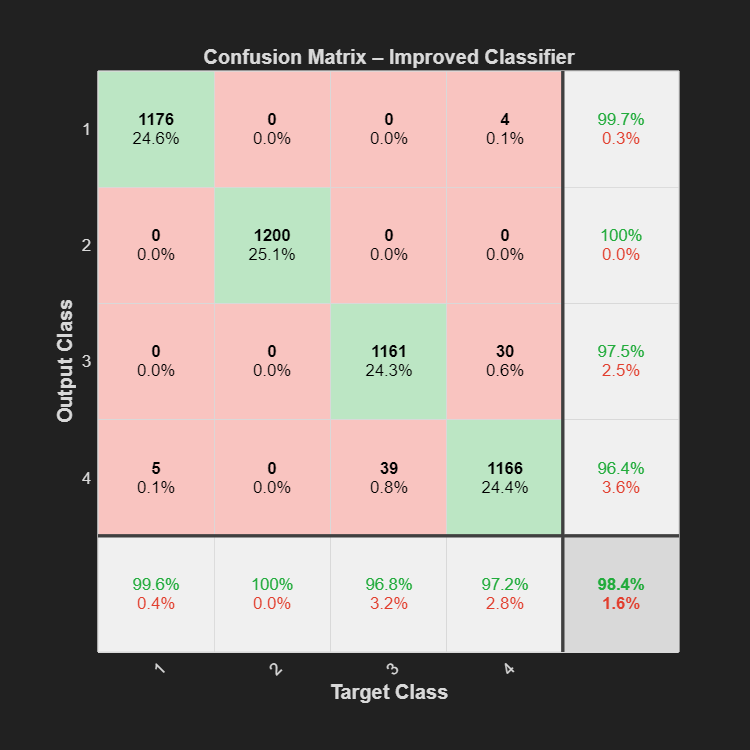


%% ---- PLOTS ----
figure; plotconfusion(Y_oh, Y_pred_f);
title('Confusion Matrix – Improved Classifier');

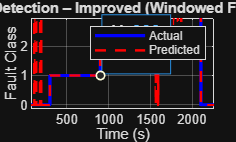


figure;
t_trim = data_f(W+1:end, 1);
plot(t_trim, fault_labels_trim, 'b', 'LineWidth', 2); hold on;
plot(t_trim, Y_pred_class', 'r--', 'LineWidth', 1.5);
legend('Actual','Predicted'); xlabel('Time (s)'); ylabel('Fault Class');
title('Fault Detection – Improved (Windowed Features)'); grid on;
ylim([-0.2 3.2]);


% Residual statistics diagnostic plot
figure;
subplot(3,1,1);
plot(t_trim, res_slp_cols(W+1:end, :));
title('Residual Slope (KEY: Drift has slope≠0, Stuck/Bias have slope≈0)');
legend('h1','h2','h3'); xlabel('Time (s)'); grid on;

subplot(3,1,2);
plot(t_trim, res_std_cols(W+1:end, :));
title('Residual Std (Drift has growing std)');
legend('h1','h2','h3'); xlabel('Time (s)'); grid on;

subplot(3,1,3);
plot(t_trim, res_mean_cols(W+1:end, :));
title('Residual Mean (Bias/Stuck have large mean)');
legend('h1','h2','h3'); xlabel('Time (s)'); grid on;


%% ---- SAVE ----
save('E:\MATLAB File\Closed Loop system\fault_models.mat', ...
     'net_fault', 'Xfps', 'W');
disp('✅ fault_models.mat saved');

✅ fault_models.mat saved
